clc
clear

data = load('data.mat');
data = data.data;

% scatter3(data(1,:), data(2,:), data(3, :))
% 
% view([10.50 67.60])

% [r, c] = size(data);
% figure(2)
% hold on
% for i = 1:c
%     if data(3, i) == 1
%         scatter(data(1, i), data(2, i), [], 'red');
%     else
%         scatter(data(1, i), data(2, i), [], 'blue');
%     end
% end

data_train = data(:, 1:2500)';
A = [data_train(:, 1).*data_train(:, 3), data_train(:, 2).*data_train(:, 3), data_train(:, 3)];
A = -1*[A, eye(2500)];

f = [1, 1, 0, 1*ones(1, 2500)];

[xx,fval,exitflag,output,lambda] = linprog(f, A, -1*ones(1, 2500), [], [], [-inf, -inf, -inf, zeros(1, 2500)]);


Optimal solution found.



xx(1:3)

ans =    -0.0445
    0.2744
   -0.5029


fval

fval = 475.7345

exitflag

exitflag = 1

output

output = struct with fields:
         iterations: 626
    constrviolation: 7.7716e-16
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 2.5580e-13


lambda

lambda = struct with fields:
      lower: [2503×1 double]
      upper: [2503×1 double]
      eqlin: []
    ineqlin: [2500×1 double]


w1 = xx(1);
w2 = xx(2);
b = xx(3);

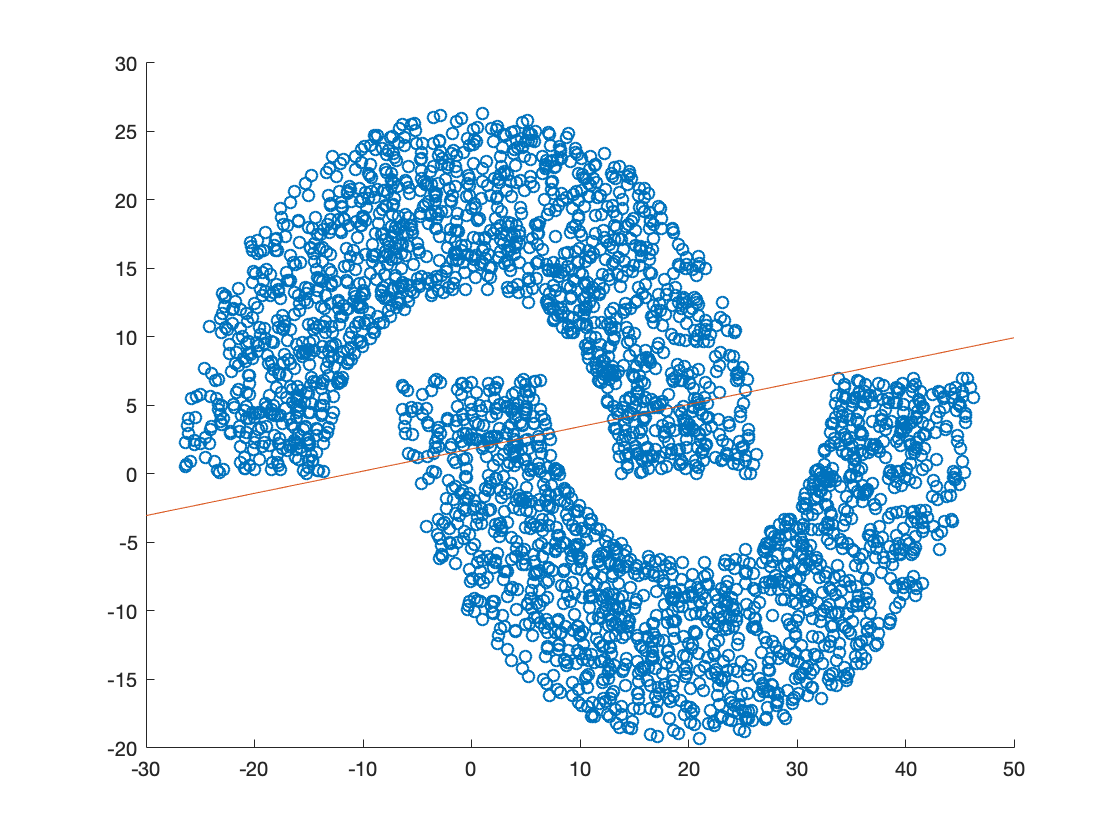

syms y(x)
y(x) = -1* x *w1/w2 - b/w2;
scatter(data(1,:), data(2,:))
hold on
plot(-30:1:50, y(-30:1:50))